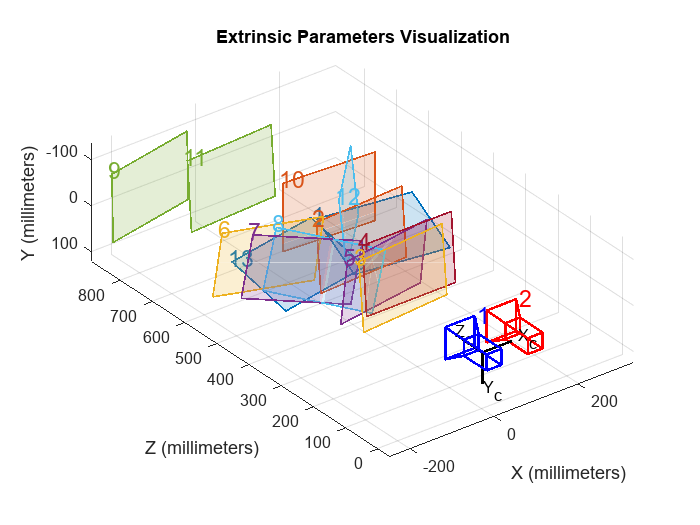

clc;
clear all;

load('stereoParams.mat');


% Visualize camera extrinsics.
showExtrinsics(stereoParams);

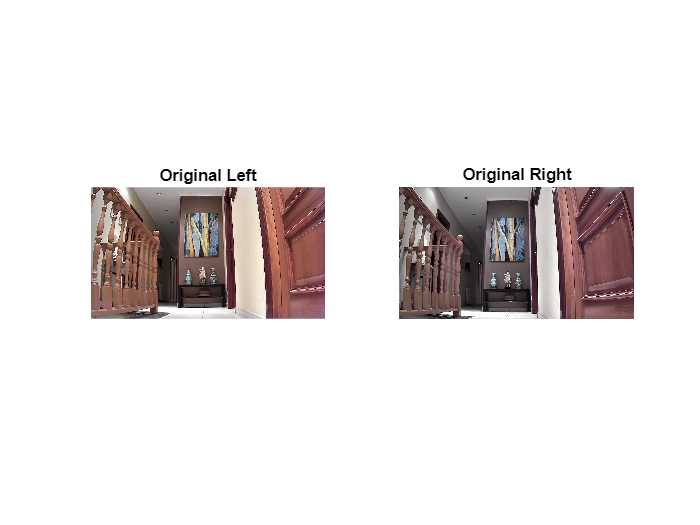

frameLeft = imread('Scripts/images/Left_pasillo/left_3.png'); 
frameRight = imread('Scripts/images/Right_pasillo/right_3.png');

frameLeftundist = undistortImage(frameLeft, stereoParams.CameraParameters1.Intrinsics);
frameRightundist = undistortImage(frameRight, stereoParams.CameraParameters2.Intrinsics);

[frameLeftRect, frameRightRect, reprojectionMatrix] = ...
    rectifyStereoImages(frameLeft, frameRight, stereoParams);

figure;
subplot(1,2,1)
imshow(frameLeft)
title('Original Left')
subplot(1,2,2)
imshow(frameRight)
title('Original Right')

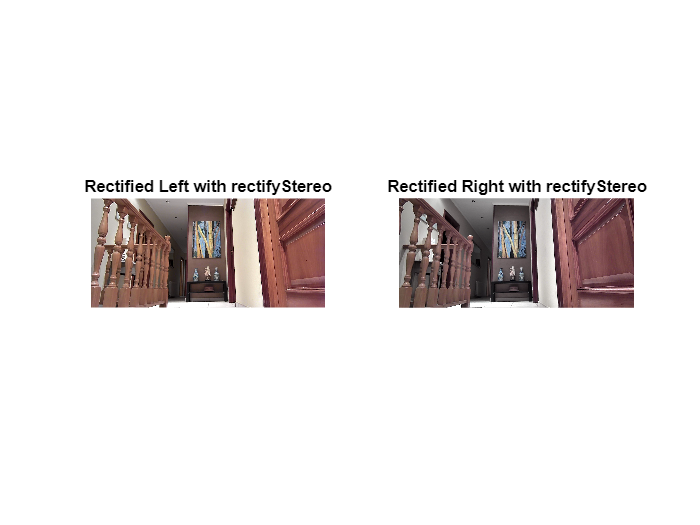


figure;
subplot(1,2,1)
imshow(frameLeftRect)
title('Rectified Left with rectifyStereo')
subplot(1,2,2)
imshow(frameRightRect)
title('Rectified Right with rectifyStereo')

Rectify stero undistorts the image and rectifies it, so all the pixels on the rigth and left frames are on the same horizontal level in order to compute the disparity map correctly. As we can see the rectified image has some distortion, another calibration must be done.

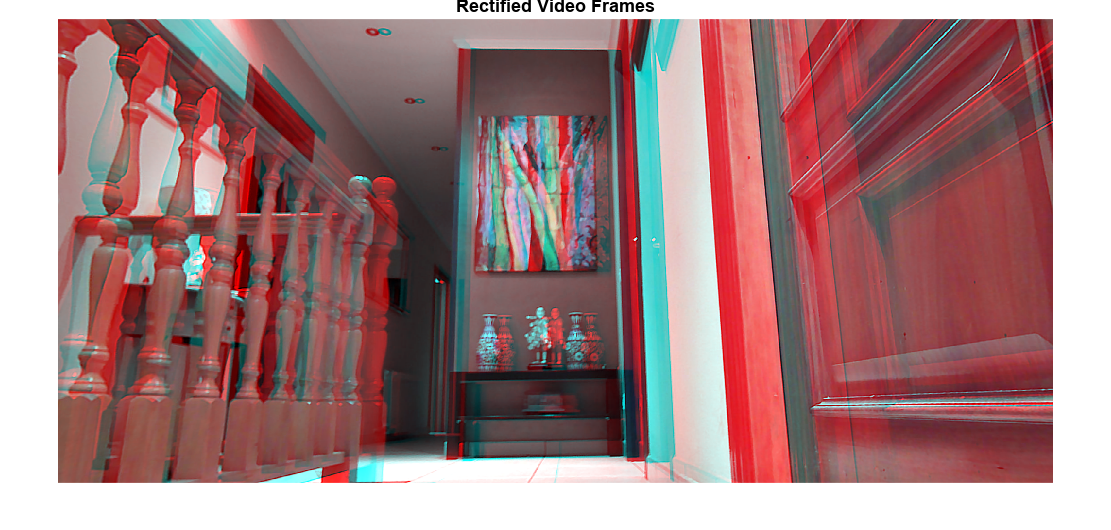

figure;
imshow(stereoAnaglyph(frameLeftRect, frameRightRect));
title('Rectified Video Frames');

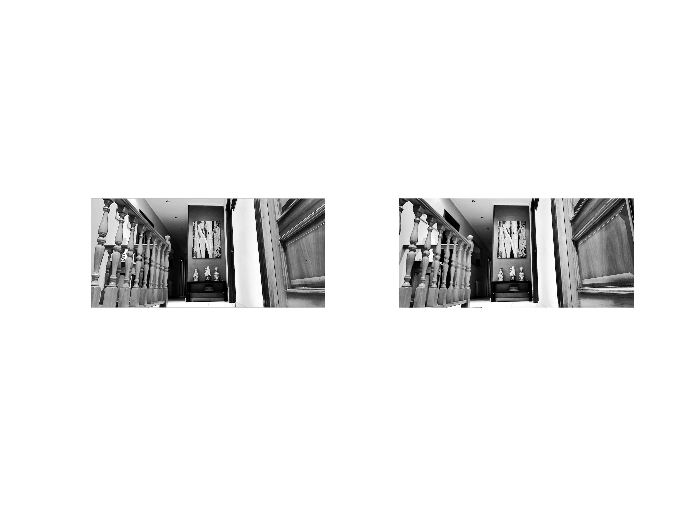

frameLeftGray  = rgb2gray(frameLeftRect);
frameRightGray = rgb2gray(frameRightRect);

imageLeftGrayHisteq = histeq(frameLeftGray);
imageRightGrayHisteq = histeq(frameRightGray);
% Crear un kernel de media móvil con un tamaño de 3x3
kernel = ones(3, 3) / 9;

% Aplicar el filtro de media móvil a la imagen de entrada
imageLeftGrayHisteq = imfilter(imageLeftGrayHisteq, kernel);
imageRightGrayHisteq = imfilter(imageRightGrayHisteq, kernel);
figure;
subplot(1, 2, 1)
imshow(imageLeftGrayHisteq)
subplot(1, 2, 2)
imshow(imageRightGrayHisteq)

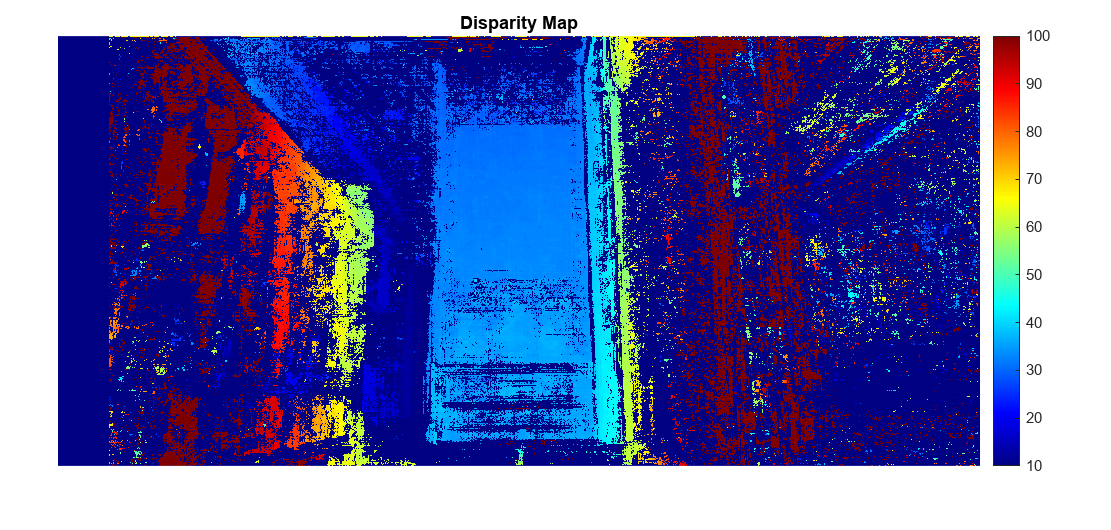

% Also disparityBM can be used to make block matching, but we can loose
% information
disparityMap = disparitySGM(imageLeftGrayHisteq, imageRightGrayHisteq);
figure;
imshow(disparityMap, [10, 100]);
title('Disparity Map');
colormap jet
colorbar

disparityMap(disparityMap < 20) = NaN;
disparityMap(disparityMap >80) = NaN;
% disparityMap(disparityMap > 50) = 0;
% figure;
% imshow(disparityMap, [0, 64]);
% title('Filtered Disparity Map');
% colormap jet
% colorbar

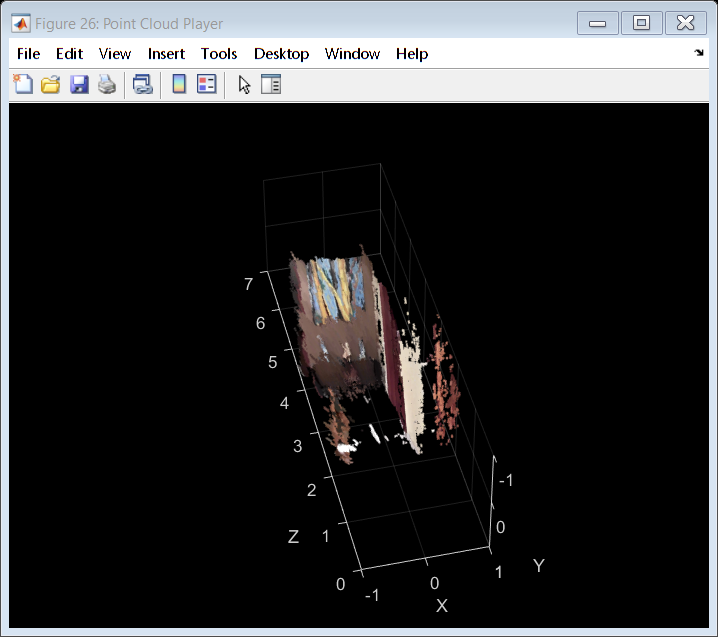

points3D = reconstructScene(disparityMap, reprojectionMatrix);

% Convert to meters and create a pointCloud object
points3D = points3D ./ 1000;
ptCloud = pointCloud(points3D, 'Color', frameLeftRect);
ptCloudOut = pcdenoise(ptCloud);

% Create a streaming point cloud viewer
player3D = pcplayer([-1, 1], [-1, 1], [0, 7], 'VerticalAxis', 'y', ...
    'VerticalAxisDir', 'down');

% Visualize the point cloud
view(player3D, ptCloudOut);

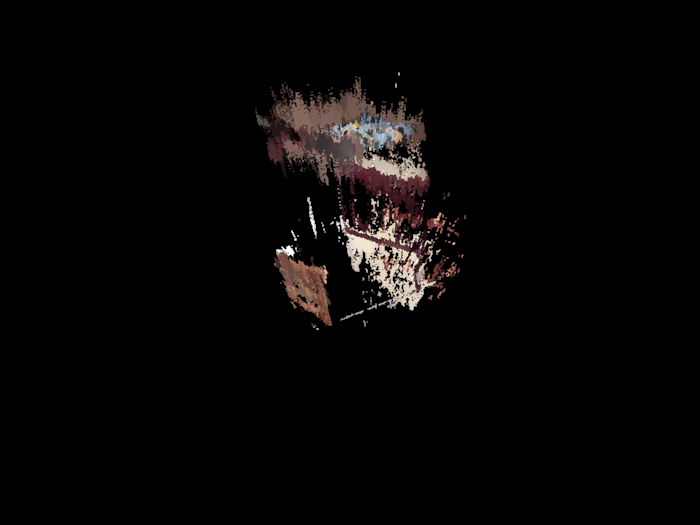

figure()
pcshow(ptCloudOut)
xlim([-1 1]);
ylim([-1 1]);
zlim([0 5]);
hold on

%pcwrite(ptCloudOut,'pasillo.ply')